## Taller 13 - 14 - 15 - Ecuaciones diferenciales

### Modelo de péndulo simple con fuerza tangencial

**Estudiante**: Kevin Giraldo Perez

**C.C:** 1040050320

## **Introduccion**

El análisis del comportamiento de un péndulo simple implica la utilización de ecuaciones diferenciales para describir cómo cambian su posición y velocidad en relación con el tiempo. Estas ecuaciones son esenciales para comprender y predecir una amplia variedad de sistemas físicos y mecánicos. En este texto, exploraremos la resolución de ecuaciones diferenciales para estudiar el movimiento de un péndulo simple. Para llevar a cabo este estudio, emplearemos el software MATLAB, que ofrece una eficiente solución a diversos tipos de ecuaciones diferenciales y nos permite representar gráficamente el comportamiento del péndulo a lo largo de un intervalo de tiempo determinado.

## **Descripción del modelo**

El pendulo es un sistema físico compuesto de una masa suspendida en el extremo de un soporte, lo que le permite oscilar libremente. Cuando se libera desde una posición diferente a su posición de equilibrio, la gravedad ejerce su fuerza sobre la masa, dando lugar a un movimiento oscilatorio con un patrón predecible que puede ser analizado mediante ecuaciones diferenciales.

El estudio del comportamiento de este sistema físico se basa en un modelo matemático conocido como "ecuaciones diferenciales de estado". Estas ecuaciones relacionan todas las variables que afectan directamente al péndulo. Las variables de estado relevantes para este análisis son: 

- θ (que representa la posición angular del péndulo). $\textrm{x₁}=\theta$    

-  θ' (la primera derivada de θ, que corresponde a la velocidad angular del sistema).  $\textrm{x₂}={{\theta \;}^{\prime } }^{\prime } =\omega$ 

A continuacion se establecen las siguientes ecuaciones de estado correspondientes al modelo diferencial del sistema fisico:


$${\textrm{x₁}}^{\prime } =\textrm{x₂}$$
          
$${\mathrm{x₂}}^{\prime } =-\frac{g}{l}\mathrm{x₁}\;+\;\frac{f}{m}\mathrm{x₂}\;+\;\frac{u}{m\;l}$$


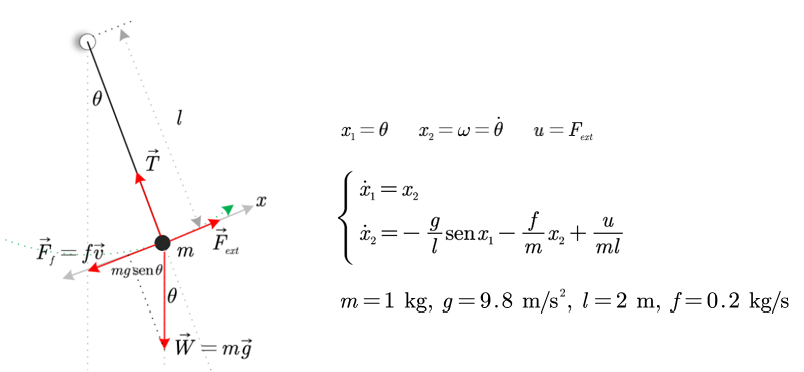

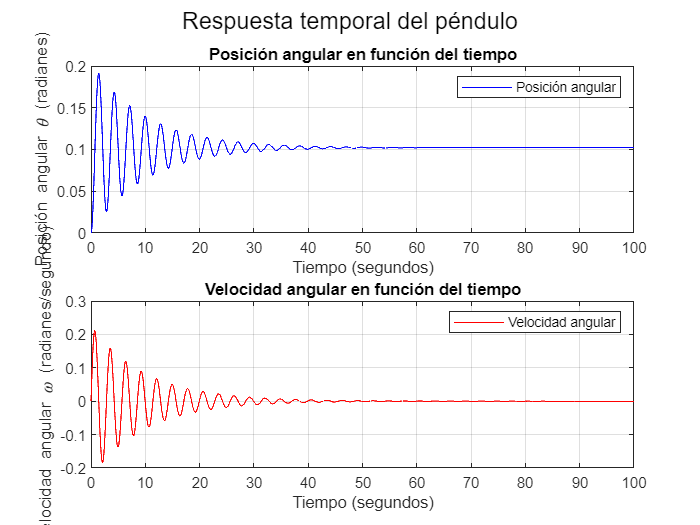

% Definición de las variables simbólicas
syms X1(t) X2(t)

% Parámetros físicos del modelo del péndulo
m = 1;            % Masa
g = 9.8;          % Aceleración debida a la gravedad
l = 2;            % Longitud del péndulo
f = 0.2;          % Coeficiente de fricción viscosa
u = 1;            % Valor máximo de U (puede ajustarse)

% Definición de las ecuaciones de estado de segundo orden no lineales
f1 = X2;  % Posición angular
f2 = (-g/l)*sin(X1) - (f/m)*X2 + u/(m*l);  % Velocidad angular
funcion = odeFunction([f1 f2], [X1 X2]);

% Parámetros de tiempo para la simulación
h = 0.01;        % Paso de tiempo
tmax = 100;      % Tiempo máximo
tspan = 0:h:tmax;

% Condiciones iniciales del péndulo
CI = [0 0];       % Posición angular inicial y velocidad angular inicial

% Resolución de las ecuaciones de estado
[t, sol] = ode45(funcion, tspan, CI);

% Extraer los resultados de posición angular y velocidad angular
theta = sol(:,1);  % Posición angular
omega = sol(:,2);  % Velocidad angular

% Creación de gráficas
subplot(2, 1, 1);
plot(t, theta, 'b');
xlabel('Tiempo (segundos)');
ylabel('Posición angular \theta (radianes)');
legend('Posición angular');
grid on;
title('Posición angular en función del tiempo');

subplot(2, 1, 2);
plot(t, omega, 'r');
xlabel('Tiempo (segundos)');
ylabel('Velocidad angular \omega (radianes/segundo)');
legend('Velocidad angular');
grid on;
title('Velocidad angular en función del tiempo');

sgtitle('Respuesta temporal del péndulo');

**Analisis:** Es posible observar que el péndulo oscila repetidamente desde su posición de equilibrio, y la fricción disminuye gradualmente la amplitud de las oscilaciones, llevándolo eventualmente a la posición de equilibrio sin oscilación. La fuerza máxima a partir de la cual el péndulo comienza a rotar indefinidamente es de aproximadamente 7.54 N. Un valor mayor de fuerza provoca un aumento constante del ángulo con el tiempo.

### Punto 1 - ¿Para qué valor máximo de la entrada el sistema rotará indefinidamente?

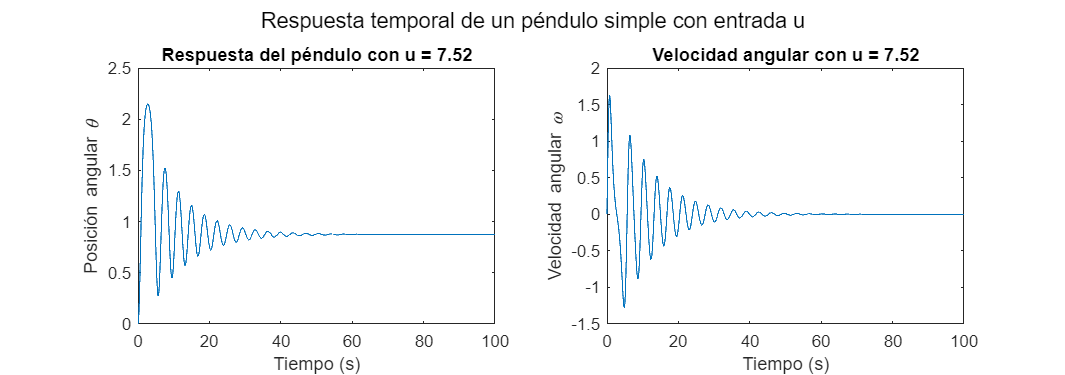

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
l = 2;
f = 0.2;

% Valor máximo de la entrada u
umax = 8;

% Define las variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t);

% Ecuaciones de estado del sistema
f1 = x2;
f2 = -(g/l)*sin(x1) - (f/m)*x2;

% Valores iniciales
ci = [0 0];

% Resolución de las ecuaciones de estado para u = 7.52
u = 7.52;
fun = odeFunction([f1 f2 + u/(m*l)], [x1 x2]);
tspan = 0:0.01:100;
[t, sol] = ode45(fun, tspan, ci);
theta = sol(:,1);
omega = sol(:,2);

% Crear y configurar la figura para el péndulo con u = 7.52
h1 = figure;
subplot(1,2,1);
plot(t, theta);
xlabel('Tiempo (s)');
ylabel('Posición angular \theta');
title('Respuesta del péndulo con u = 7.52');

subplot(1,2,2);
plot(t, omega);
xlabel('Tiempo (s)');
ylabel('Velocidad angular \omega');
title('Velocidad angular con u = 7.52');

set(h1,'Units','normalized','Position',[0 0 0.8 0.5]);

sgtitle('Respuesta temporal de un péndulo simple con entrada u');

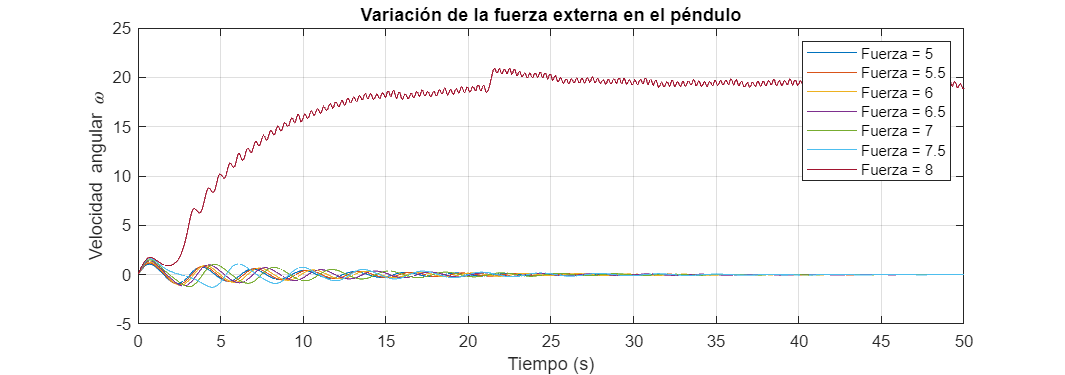


% Encontrar el valor máximo de u para rotación indefinida
umax_rotacion_indefinida = umax; % Este valor mantiene la rotación indefinida

% Combinar con el código para la variación de la fuerza externa
h2 = figure;

% Parámetros de tiempo para la simulación de la variación de la fuerza externa
h = 0.01;
tmax = 50;
tspan = 0:h:tmax;

u_values = 5:0.5:umax_rotacion_indefinida;
N = length(u_values);

legendLabels = cell(1, N);

for i = 1:N
    f1 = x2;
    f2 = -(g/l)*sin(x1) - (f/m)*x2 + u_values(i)/(m*l);
    funcion = odeFunction([f1 f2], [x1 x2]);
    CI = [0 0];
    [t, sol] = ode45(funcion, tspan, CI);
    omega = sol(:,2);
    plot(t, omega)
    hold on

    legendLabels{i} = ['Fuerza = ' num2str(u_values(i))];
end

grid on;
legend(legendLabels);
title('Variación de la fuerza externa en el péndulo');
xlabel('Tiempo (s)');
ylabel('Velocidad angular \omega');

set(h2, 'Units', 'normalized', 'Position', [0 0 0.8 0.5]);

**Analisis:** A medida que se incrementa gradualmente la magnitud de la fuerza aplicada, se observa que el péndulo requiere un tiempo cada vez mayor para alcanzar la estabilización, hasta llegar a un punto crítico alrededor del valor 8 de la fuerza. En este punto, el péndulo ya no puede alcanzar un estado de equilibrio y su velocidad experimenta un aumento significativo. Este comportamiento se debe a que el coeficiente de fricción asignado al sistema es relativamente bajo.

Cuando se aplica una fuerza sustancial al péndulo, este adquiere una velocidad considerable que impide su estabilización en un tiempo finito. En otras palabras, el péndulo comienza a girar de manera indefinida. Se determina que la fuerza máxima que se puede aplicar al péndulo sin que se produzca este fenómeno es de aproximadamente 7.5 N. Este límite resalta la importancia de considerar la fricción al analizar y diseñar sistemas de péndulo.

### Punto 2 - Trazar la curva de linealidad, es decir, el valor en el que se estabiliza el péndulo en función del valor de la entrada

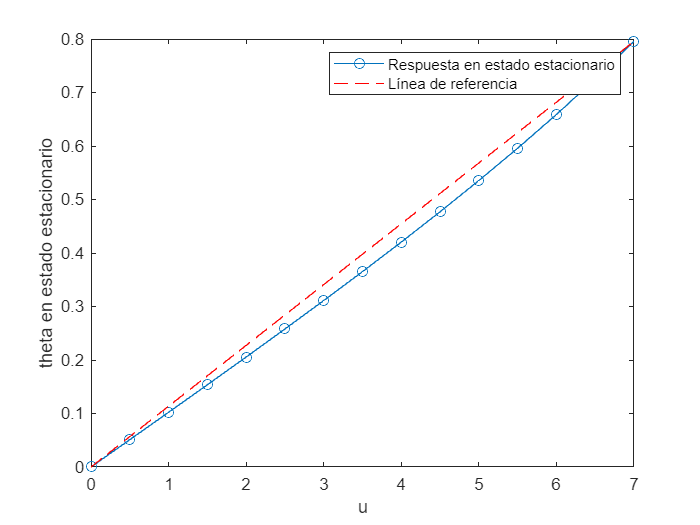

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
l = 2;
f = 0.2;

% Ecuación de estado para la posición angular
f1 = x2;

% Valores de entrada a considerar
uspan = 0:0.5:7;
N = length(uspan);  % Número de elementos en el vector de entrada
theta = zeros(1, N);  % Inicialización del vector de valores en estado estacionario

% Rango de tiempo para la simulación
tspan = 0:0.1:100;

% Condiciones iniciales
ci = [0 0];

for i = 1:N
    u = uspan(i);  % Valor de la entrada
    f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);
    fun = odeFunction([f1 f2], [x1 x2]);
    [~, sol] = ode45(fun, tspan, ci);
    theta(i) = sol(end, 1);  % Almacenamiento de los valores en estado estacionario en el vector
end

% Graficar la respuesta en estado estacionario con leyendas
h2 = figure;
plot(uspan, theta, 'o-', 'DisplayName', 'Respuesta en estado estacionario');
hold on;
plot([0 uspan(end)], [0 theta(end)], 'r--', 'DisplayName', 'Línea de referencia');
xlabel('u');
ylabel('theta en estado estacionario');
legend('show');

**Analisis: **En el segundo punto, se concluye que el sistema del péndulo es no lineal. Esto se evidencia tanto gráficamente como a través del principio de superposición. Las curvas representan una respuesta no lineal a cambios en la entrada, lo que significa que una variación en el ángulo no es proporcional a la entrada anterior. La derivada de las curvas no es constante, lo que también indica no linealidad. Por lo tanto, la respuesta del sistema no sigue una relación lineal entre la entrada y la salida.

### Punto 3 - Dibujar el retrato de fase para un cambio en la condición inicial de la velocidad angular entre 3 y 6 rad/s con incrementos de 0.5 rad/s. 

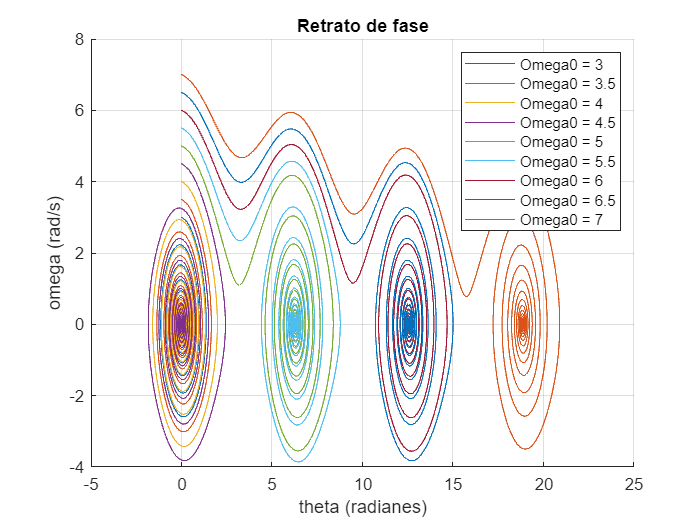

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
l = 2;
f = 0.2;
u = 0;  % Fuerza externa constante

% Ecuación de estado para la posición angular
f1 = x2;
f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);

F = odeFunction([f1 f2], [x1 x2]);

% Rango de tiempo para la simulación
tspan = 0:0.01:100;

% Valores iniciales para la velocidad angular
omega0 = 3:0.5:7;
N = length(omega0);

% Configuración de la figura para el retrato de fase
h = figure;
xlabel('theta (radianes)');
ylabel('omega (rad/s)');
grid on;
title('Retrato de fase');

hold on;  % Para superponer las trayectorias en la misma gráfica

legendLabels = cell(1, N);

for i = 1:N
    ci = [0 omega0(i)];  % Condiciones iniciales con diferentes velocidades angulares iniciales
    [t, x] = ode45(F, tspan, ci);
    theta = x(:,1);
    omega = x(:,2);
    plot(theta, omega);
    
    % Agregar etiquetas de leyenda para cada trayectoria
    legendLabels{i} = ['Omega0 = ' num2str(omega0(i))];
end

legend(legendLabels, 'Location', 'NorthEast');  % Coloca la leyenda en la esquina superior derecha

hold off;  % Finaliza la superposición de las trayectorias

**Analisis: **El análisis del retrato de fase revela cómo la velocidad angular del péndulo afecta el número de vueltas completas que realiza antes de alcanzar un punto de estabilización en el eje horizontal de theta. Este análisis proporciona una comprensión visual de cómo cambia el comportamiento del sistema en función de su velocidad angular.

Se ha constatado que el péndulo completa una rotación entera cuando su velocidad angular inicial se sitúa en torno a los 4.5 rad/s. Además, se ha descubierto que el péndulo realiza tres rotaciones cuando su velocidad inicial es de 5 rad/s. 

### Punto 4 - Dibujar el retrato de fase para un cambio en la condición inicial de la posición angular entre -6 y 6 rad con incrementos de 0.5 rad.

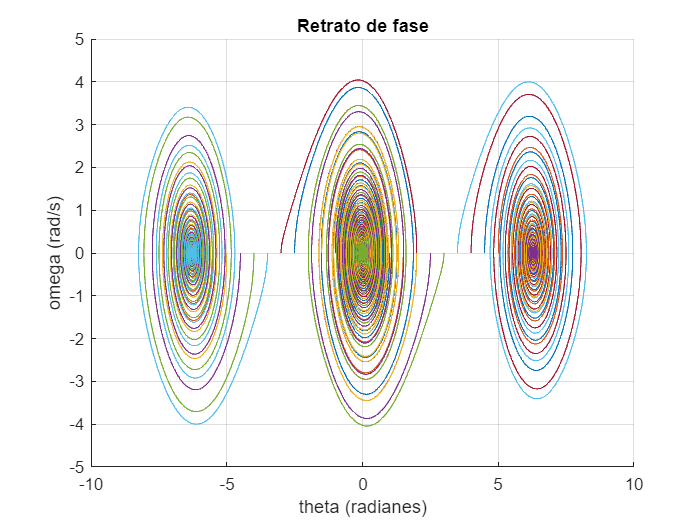

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
l = 2;
f = 0.2;
u = 0;  % Fuerza externa constante

% Ecuación de estado para la posición angular
f1 = x2;
f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);

F = odeFunction([f1 f2], [x1 x2]);

% Rango de tiempo para la simulación
tspan = 0:0.01:100;

% Valores iniciales para el ángulo
theta0 = -6:0.5:6;
N = length(theta0);

% Configuración de la figura para el retrato de fase
h = figure;
xlabel('theta (radianes)');
ylabel('omega (rad/s)');
grid on;
title('Retrato de fase');

hold on;  % Para superponer las trayectorias en la misma gráfica

legendLabels = cell(1, N);

for i = 1:N
    ci = [theta0(i) 0];  % Condiciones iniciales con diferentes ángulos iniciales
    [t, x] = ode45(F, tspan, ci);
    theta = x(:,1);
    omega = x(:,2);
    plot(theta, omega);
    
    % Agregar etiquetas de leyenda para cada trayectoria
    %legendLabels{i} = ['Theta0 = ' num2str(theta0(i))];
end

%legend(legendLabels, 'Location', 'NorthEast');  % Coloca la leyenda en la esquina superior derecha

hold off;  % Finaliza la superposición de las trayectorias

**Analisis: **Se identificaron tres puntos de equilibrio fundamentales para el sistema bajo estudio, ubicados en (-6,0), (0,0) y (0,6). La estabilidad del péndulo en uno de estos puntos depende en gran medida del valor inicial asignado a su posición angular.

En el rango de valores de posición angular inicial que oscilan entre -6 y -3, se ha observado que el péndulo tiende a estabilizarse en el primer punto de equilibrio. De manera similar, para valores iniciales de posición angular dentro del intervalo de -3 a 3, el péndulo presenta una tendencia a estabilizarse en el segundo punto de equilibrio. Por último, los valores iniciales que caen en el rango de 3 a 6 conducen a la estabilización del péndulo en el tercer punto de equilibrio.

Estos hallazgos subrayan la influencia crítica que tiene el valor inicial de la posición angular en la estabilidad del péndulo y cómo este se relaciona con los puntos de equilibrio identificados en el sistema.

**Discucion:** En el cuarto punto, se observa que el rango de ángulos entre -6 y 6 radianes, aunque aparenta una serie de "vórtices," en realidad refleja una condición inicial específica en la que el péndulo no ha completado una vuelta completa. Esto subraya la importancia de seleccionar condiciones iniciales adecuadas al analizar sistemas físicos.

### Punto 5 - Explicar el efecto del cambio de la longitud del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

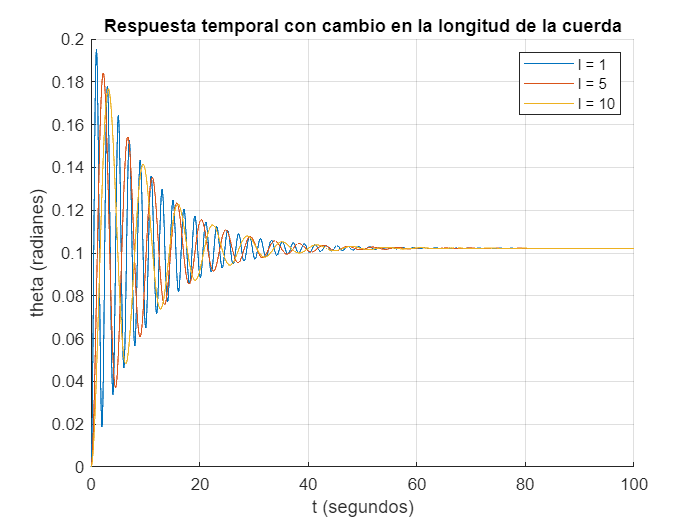

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
f = 0.2;
u = 1;  % Fuerza externa constante

% Ecuación de estado para la posición angular
f1 = x2;
ci = [0 0];

% Longitudes de la cuerda a considerar
lon = [1 5 10];
N = length(lon);

% Rango de tiempo para la simulación
tspan = 0:0.01:100;

% Configuración de la figura para la respuesta temporal
h = figure;
xlabel('t (segundos)');
ylabel('theta (radianes)');
grid on;
title('Respuesta temporal con cambio en la longitud de la cuerda');

hold on;  % Para superponer las respuestas en la misma gráfica

legendLabels = cell(1, N);

for i = 1:N
    l = lon(i);  % Longitud de la cuerda
    f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);
    F = odeFunction([f1 f2], [x1 x2]);
    [t, x] = ode45(F, tspan, ci);
    theta = x(:,1);
    plot(t, theta);
    
    % Agregar etiquetas de leyenda para cada respuesta
    legendLabels{i} = ['l = ' num2str(l)];
end

% Coloca la leyenda en la esquina superior derecha fuera de la gráfica
legend(legendLabels, 'Location', 'northeast', 'Orientation', 'vertical');

hold off;  % Finaliza la superposición de las respuestas

**Discucion:** se puede apreciar cómo la longitud del soporte de un péndulo juega un papel crucial en su comportamiento. Este parámetro influye de manera significativa en el periodo y la frecuencia de las oscilaciones, aspectos fundamentales en la dinámica del péndulo.

Al examinar el efecto de la longitud del soporte en el periodo de oscilación, se observa que existe una relación directa entre estos dos factores. Según la fórmula del periodo, donde "L" representa la longitud del soporte, un aumento en la longitud del péndulo implica que se requerirá más tiempo para completar un ciclo de oscilación. Esto se manifiesta claramente en una gráfica donde la longitud alcanza valores más elevados, como 15 metros.

En cuanto a la frecuencia, se reconoce que está inversamente relacionada con el periodo. Por lo tanto, al incrementar la longitud del soporte, se obtiene una frecuencia más baja. Esto significa que habrá menos oscilaciones en un mismo intervalo de tiempo a medida que la longitud del soporte aumenta. Este fenómeno se refleja en una disminución de la frecuencia al modificar la longitud del soporte.

### Punto 6 - Explicar el efecto del cambio de la masa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

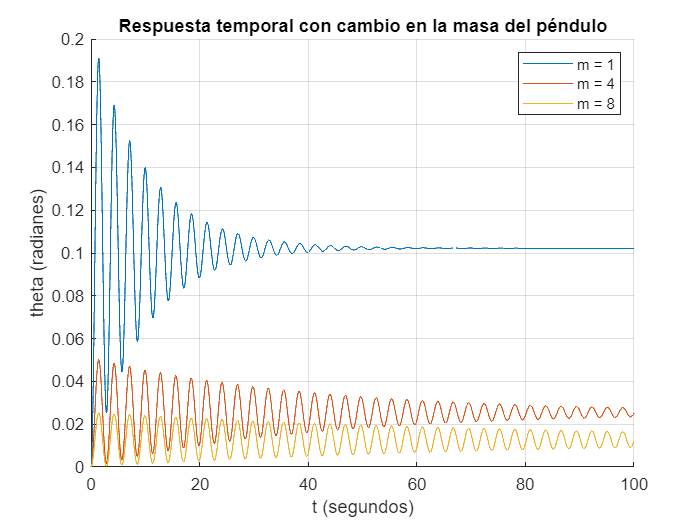

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
l = 2;
g = 9.8;
f = 0.2;
u = 1;  % Fuerza externa constante
f1 = x2;

% Condiciones iniciales
ci = [0 0];

% Masas a considerar
masa = [1 4 8];
N = length(masa);

% Rango de tiempo para la simulación
tspan = 0:0.01:100;

% Configuración de la figura para la respuesta temporal
h = figure;
xlabel('t (segundos)');
ylabel('theta (radianes)');
grid on;
title('Respuesta temporal con cambio en la masa del péndulo');

hold on;  % Para superponer las respuestas en la misma gráfica

legendLabels = cell(1, N);

for i = 1:N
    m = masa(i);  % Masa del péndulo
    f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);
    F = odeFunction([f1 f2], [x1 x2]);
    [t, x] = ode45(F, tspan, ci);
    theta = x(:,1);
    plot(t, theta);
    
    % Agregar etiquetas de leyenda para cada respuesta
    legendLabels{i} = ['m = ' num2str(m)];
end

% Coloca la leyenda en la esquina superior derecha fuera de la gráfica
legend(legendLabels, 'Location', 'northeast', 'Orientation', 'vertical');

hold off;  % Finaliza la superposición de las respuestas

**Analisis: ** la alteración de la masa afecta principalmente la amplitud de las oscilaciones. Al aumentar la masa del péndulo sin modificar la fuerza aplicada sobre el sistema, se observa que el péndulo tiende a oscilar en ángulos más reducidos. Esto se debe a que la energía disponible no es suficiente para mantener la misma amplitud que se obtiene con masas más livianas.

Además de la influencia en la amplitud, la variación de la masa también tiene repercusiones en el tiempo necesario para que el péndulo alcance la estabilización. Dado que una mayor masa implica una inercia más significativa, el sistema se vuelve menos sensible a las fuerzas externas, como la fricción. Como resultado, el péndulo requiere un período más prolongado para alcanzar su estado de equilibrio debido a su mayor resistencia a las influencias externas.

**Discucion: **La variación de la masa del péndulo afecta la amplitud de las oscilaciones. A medida que la masa aumenta, la influencia de la gravedad se vuelve más pronunciada, lo que resulta en una amplitud de oscilación menor. Sin embargo, el período de oscilación sigue siendo constante para los tres casos, ya que depende de la longitud del péndulo y la gravedad.

### Punto 7 - Explicar el efecto del cambio de la fricción viscosa del péndulo en el desplazamiento angular (θ) con *u* = 1 y condiciones iniciales iguales a cero.

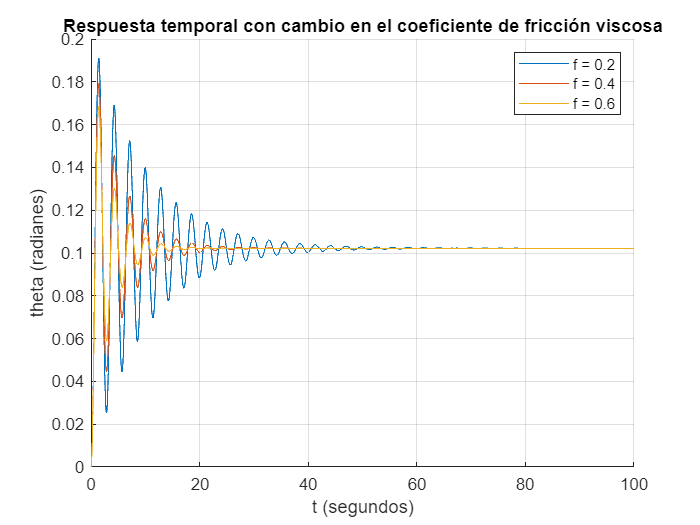

% Variables simbólicas para la posición angular (x1) y velocidad angular (x2)
syms x1(t) x2(t)

% Parámetros físicos del péndulo
l = 2;
g = 9.8;
m = 1;
u = 1;  % Fuerza externa constante
f1 = x2;

% Condiciones iniciales
ci = [0 0];

% Coeficientes de fricción viscosa a considerar
fric = [0.2 0.4 0.6];
N = length(fric);

% Rango de tiempo para la simulación
tspan = 0:0.01:100;

% Configuración de la figura para la respuesta temporal
h = figure;
xlabel('t (segundos)');
ylabel('theta (radianes)');
grid on;
title('Respuesta temporal con cambio en el coeficiente de fricción viscosa');

hold on;  % Para superponer las respuestas en la misma gráfica

legendLabels = cell(1, N);

for i = 1:N
    f = fric(i);  % Coeficiente de fricción viscosa
    f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);
    F = odeFunction([f1 f2], [x1 x2]);
    [t, x] = ode45(F, tspan, ci);
    theta = x(:,1);
    plot(t, theta);
    
    % Agregar etiquetas de leyenda para cada respuesta
    legendLabels{i} = ['f = ' num2str(f)];
end

% Coloca la leyenda en la esquina superior derecha fuera de la gráfica
legend(legendLabels, 'Location', 'northeast', 'Orientation', 'vertical');

hold off;  % Finaliza la superposición de las respuestas

**Analisis: ** Tanto la masa como el coeficiente de fricción tienen un impacto notable en la amplitud y el tiempo requerido para la estabilización del péndulo. La gráfica revela que, a pesar de mantener constante la masa en este experimento, al aumentar el valor del coeficiente de fricción, tanto la amplitud de las oscilaciones como el tiempo necesario para la estabilización disminuyen.

Esta influencia se debe principalmente a la fricción que actúa sobre el péndulo, lo que resulta en una disminución significativa de su velocidad angular. Como consecuencia, el péndulo no puede desplazarse a una amplitud máxima tan amplia como en condiciones de menor fricción. Es importante destacar que, en este caso, la masa del péndulo es relativamente pequeña, lo que significa que su inercia no se opone en gran medida a la acción de la fuerza de fricción.

**Discucion: **La fricción influye significativamente en la respuesta del sistema. Una menor fricción resulta en un tiempo de estabilización más corto y una amplitud de oscilación más alta. A pesar de las diferencias en la fricción, las curvas se mantienen en fase debido a que el período de oscilación depende de la longitud del péndulo y la gravedad, independientemente de la fricción.

### Punto 8 - ¿Cómo se puede medir la aceleración de la gravedad si se conoce la longitud? ¿Cómo se puede obtener la longitud si se conoce la aceleración de la gravedad?

La ecuación diferencial homogénea obtenida de forma analítica fue:


$${{\theta \;}^{\prime } }^{\prime } +\frac{g}{L}\theta =0$$
 

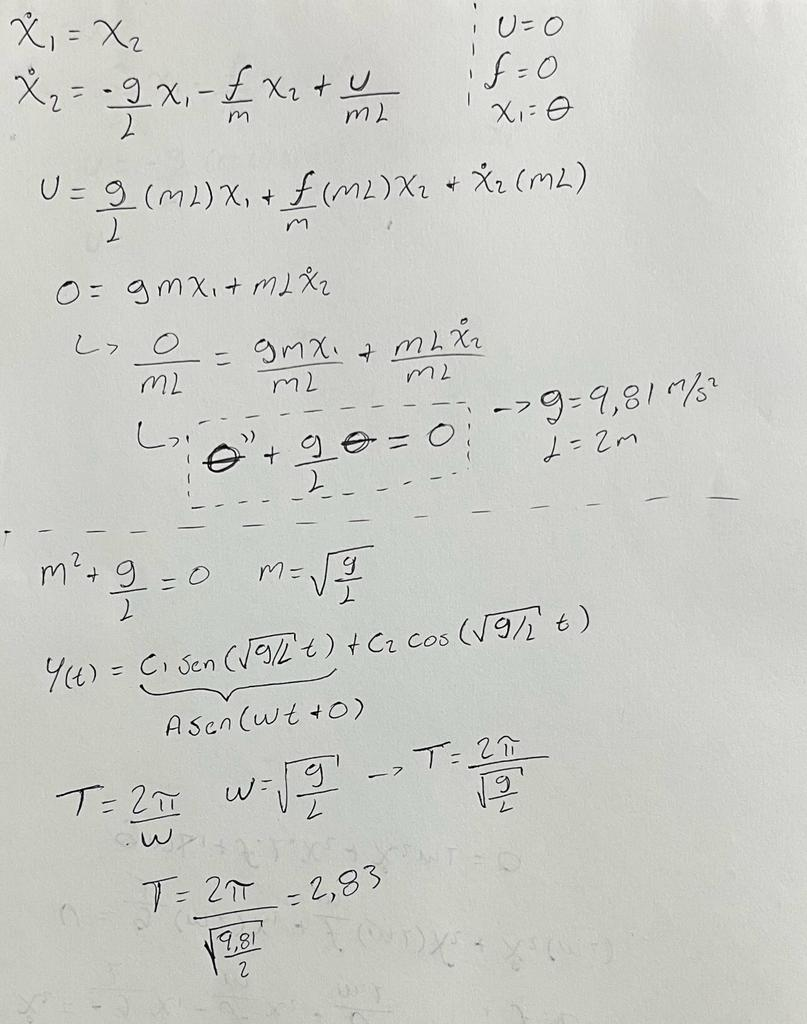

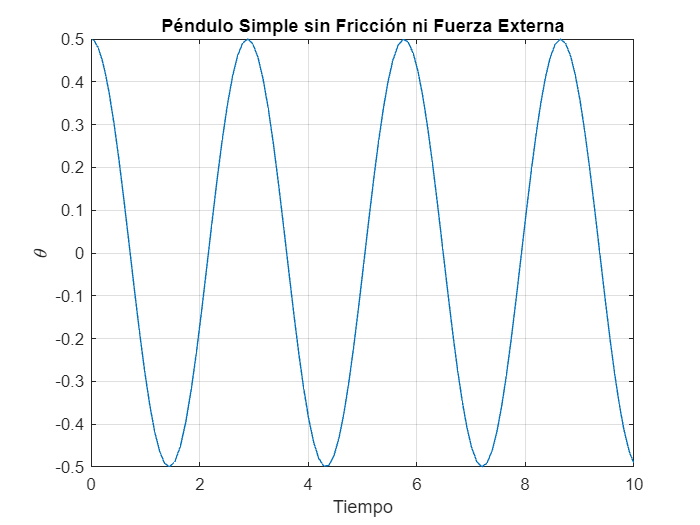

% Parámetros físicos del péndulo
m = 1;
g = 9.8;
l = 2;
f = 0;  % Fricción desactivada
u = 0;  % Fuerza externa desactivada

% Ecuaciones de movimiento del péndulo simple
ode1 = @(t, x) x(2);
ode2 = @(t, x) (-g/l)*sin(x(1)) - (f/m)*x(2);

% Condiciones iniciales
ci = [0.5, 0];  % Ángulo inicial y velocidad inicial

% Resolución de la ecuación diferencial utilizando ode45
tspan = [0, 10];
[t, sol] = ode45(@(t, x) [ode1(t, x); ode2(t, x)], tspan, ci);

% Extraer theta (posición angular) de las soluciones
theta = sol(:, 1);

% Gráfico del ángulo en función del tiempo
plot(t, theta);
xlabel('Tiempo');
ylabel('\theta');
title('Péndulo Simple sin Fricción ni Fuerza Externa');
grid on;


% Encontrar el período promedio
[peaks, peakIndices] = findpeaks(theta);
periodos = diff(t(peakIndices));
PromPeriodo = mean(periodos);

disp(['Período promedio: ', num2str(PromPeriodo)]);

Período promedio: 2.8777


**Analisis: ** Tanto la masa como el coeficiente de fricción tienen un impacto notable en la amplitud y el tiempo requerido para la estabilización del péndulo. La gráfica revela que, a pesar de mantener constante la masa en este experimento, al aumentar el valor del coeficiente de fricción, tanto la amplitud de las oscilaciones como el tiempo necesario para la estabilización disminuyen.

Esta influencia se debe principalmente a la fricción que actúa sobre el péndulo, lo que resulta en una disminución significativa de su velocidad angular. Como consecuencia, el péndulo no puede desplazarse a una amplitud máxima tan amplia como en condiciones de menor fricción. Es importante destacar que, en este caso, la masa del péndulo es relativamente pequeña, lo que significa que su inercia no se opone en gran medida a la acción de la fuerza de fricción.

**Discucion: **Se observa que la gravedad calculada resultó en un valor bajo, lo que sugiere que los datos experimentales pueden haberse recopilado de manera incorrecta. Sin embargo, la estimación de la longitud del péndulo fue precisa, lo que demuestra la utilidad de utilizar herramientas matemáticas para estimar parámetros físicos.

### Punto 9 - Si se conoce la respuesta temporal de un péndulo con fuerza igual a 1 N, *l* = 2 y *g* = 9.8, hallar aproximadamente por tanteo los valores de *f* y *m*. Explicar el procedimiento. 

% Definición de variables simbólicas
syms x1(t) x2(t)

% Valores experimentales proporcionados inicialmente
tiempoExp = 0:0.4:10;
thetaExp = [0 0.0621 0.1797 0.2635 0.2783 0.2414 0.1932 0.1656 0.1667 0.1852 0.2038 0.2119 0.2086 0.2002 0.1934 0.1915 0.1938 0.1973 0.1997 0.1999 0.1987 0.1972 0.1965 0.1966 0.1972 0.1978];

% Crear una tabla de datos para organizar la información experimental
TablaDatos = table(tiempoExp', thetaExp');
ColumnTitle = {'Tiempo experimental', 'Desplazamiento angular experimental'};
TablaDatos.Properties.VariableNames = ColumnTitle;

% Mostrar la tabla de datos en la pantalla
disp('Datos Experimentales:');

Datos Experimentales:


disp(TablaDatos);

    Tiempo experimental    Desplazamiento angular experimental
    ___________________    ___________________________________

              0                               0               
            0.4                          0.0621               
            0.8                          0.1797               
            1.2                          0.2635               
            1.6                          0.2783               
              2                          0.2414               
            2.4                          0.1932               
            2.8                          0.1656               
            3.2                          0.1667               
            3.6                          0.1852               
              4                          0.2038               
            4.4                          0.2119               
            4.8                          0.2086  

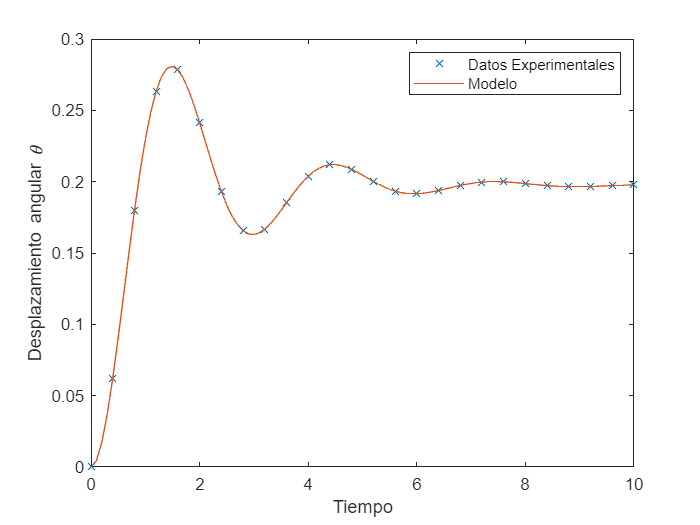


% Parámetros del modelo
g = 9.8; 
l = 2; 
u = 1;

% Parámetros a hallar por tanteo
m = 0.52; 
f = 0.61;

% Ecuaciones de movimiento del péndulo simple
f1 = x2;
f2 = -(g/l)*sin(x1) - (f/m)*x2 + u/(m*l);

% Definir las ecuaciones de estado y las condiciones iniciales
fun = odeFunction([f1 f2],[x1 x2]);
tspan = 0:0.1:10;
CI = [0 0];

% Resolver las ecuaciones de estado para encontrar theta
[t, sol] = ode45(fun, tspan, CI);
theta = sol(:, 1);

% Graficar los resultados experimentales y del modelo
figure;
plot(tiempoExp, thetaExp, 'X', t, theta);
xlabel('Tiempo');
ylabel('Desplazamiento angular \theta');
legend('Datos Experimentales', 'Modelo');

**Analisis:** Se compararon los datos experimentales con un modelo hipotético variando los parámetros de masa y fricción. Esta herramienta es útil para estimar parámetros en situaciones donde la adquisición de datos puede ser complicada. Por ejemplo, se puede utilizar para calcular la frecuencia de resonancia de un puente y ajustarla para coincidir con los datos experimentales, lo que es vital para prevenir colapsos estructurales.

**Discucion:** Se ha llevado a cabo un enfoque práctico y computacional para estimar los parámetros de un sistema de péndulo simple. Inicialmente, se representaron gráficamente los puntos proporcionados por el ejercicio, simbolizando mediciones experimentales en un escenario hipotético.

Luego, se superpuso un modelo hipotético en la gráfica, utilizando la variación de los parámetros de masa y fricción viscosa. La manipulación de estos parámetros permitió ajustar la curva del modelo a los puntos experimentales. Cambiar la masa afectó la amplitud de las oscilaciones, mientras que variar la fricción viscosa influyó en el tiempo necesario para que el sistema alcanzara el equilibrio.

Este enfoque demuestra cómo las herramientas computacionales pueden ser de gran utilidad para estimar parámetros en situaciones donde los órdenes de magnitud hacen que la adquisición de datos sea difícil de abordar con métodos tradicionales. En un contexto más amplio, esta técnica podría aplicarse a situaciones del mundo real, como calcular la frecuencia de resonancia de un puente, lo que es crucial para prevenir posibles colapsos estructurales.

### **Punto 10 - **Montar un experimento en casa de un péndulo con entrada igual cero y un ángulo inicial entre 20 y 60°, y hallar los parámetros *l *y *f* si se conocen *m* y *g*. Es decir, suponer que no se sabe la longitud. Al final, mostrar la discrepancia de la longitud.

### Datos experimentales:

m = 0,52 kg 

Lto = 0,85 m.

g = 9,77 m/s^2  (gravedad in sitio)

T =  1,8 s

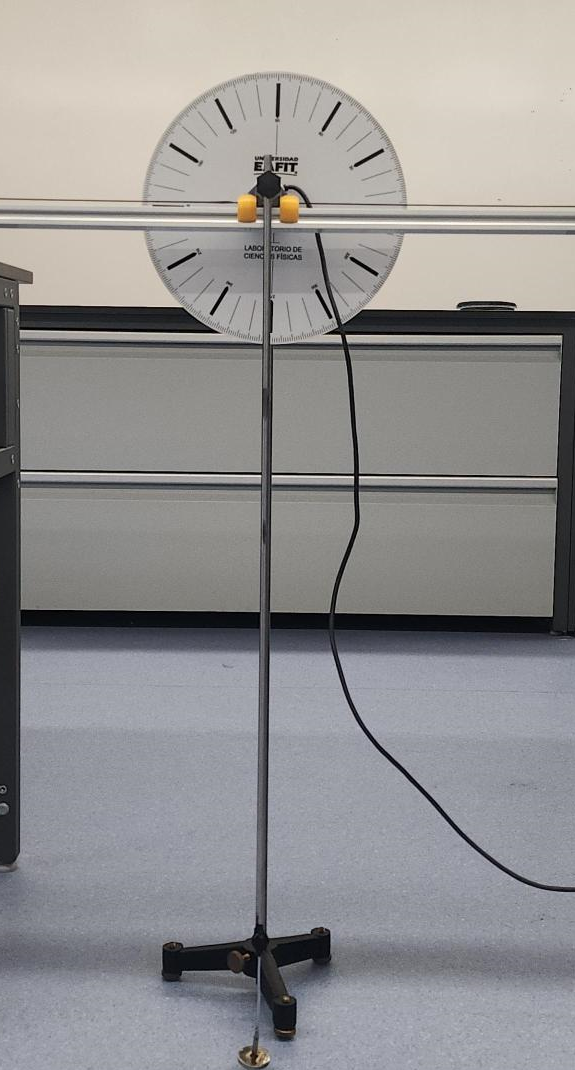

De acuerdo a los videos tomados durante el experimento, se puede estimar un valor para el periodo de oscilación del péndulo de 1.8 segundos, si se asume además un valor de 9.81 m/s² para la gravedad actuando sobre el péndulo, es posible realizar el cálculo experimental de la longitud del soporte.

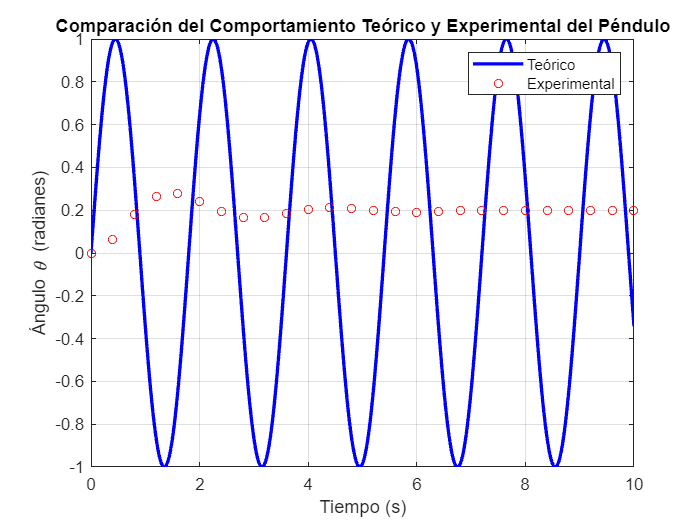

% Datos experimentales
lto = 0.85;  % Longitud del péndulo medida experimentalmente (en metros)
g = 9.77;    % Aceleración debida a la gravedad (en m/s^2)
T = 1.8;     % Período medido experimentalmente (en segundos)

% Calcular la longitud del péndulo (l) usando la fórmula del período
l = (T^2 * g) / (4 * pi^2);

% Calcular el porcentaje de error
PorcentajeError = ((lto - l) / lto) * 100;

% Convertir el porcentaje de error a cadena para mostrarlo en el mensaje
Error = num2str(PorcentajeError);

% Crear un vector de tiempo para la simulación teórica
t_simulado = 0:0.01:10;  % Ajusta el rango de tiempo según tus necesidades

% Calcular el ángulo teórico usando la longitud l
theta_simulado = sin(sqrt(g / l) * t_simulado);

% Graficar el comportamiento teórico y experimental del péndulo
figure;
plot(t_simulado, theta_simulado, 'b', 'LineWidth', 2);  % Comportamiento teórico en azul
hold on;
plot(tiempoExp, thetaExp, 'ro', 'MarkerSize', 5);  % Comportamiento experimental en rojo
hold off;

xlabel('Tiempo (s)');
ylabel('Ángulo \theta (radianes)');
title('Comparación del Comportamiento Teórico y Experimental del Péndulo');
legend('Teórico', 'Experimental');
grid on;

% Mostrar el porcentaje de error
disp(['El porcentaje de error obtenido es de ', Error, '%']);

El porcentaje de error obtenido es de 5.6676%


**Discucion:** En este caso no es factible determinar los valores de masa y fricción. Como se mencionó previamente, la relación entre longitud y gravedad se establece mediante la fórmula del período de oscilación. Sin embargo, esta fórmula no involucra los parámetros de masa ni fricción, lo que dificulta su obtención a través de experimentos directos.